# **SHORT TERM FOURIER TRANSFORM ANALYSIS**

**An analysis of a non-stationary signal will be performed through the STFT which allows to analyze the frequency components with respect to different times. It should be noted the difference with respect to the FT which allows to analyze the frequency components in "all times", ie from -infty to +infty since these are equal in "all times" as per the analytic definition.**

clear; close all; clc;

Specify the parameters of a signal with a sampling frequency of 1 kHz and a signal duration of 1.5 seconds.

fs = 1000;            % Sampling frequency                    
ts = 1/fs;            % Sampling period       
l = 1500;             % Length of signal
t = (0:l-1)*ts;       % Time vector
f = fs*(0:(l/2))/l;   % Scaling

Form a signal of sinusoid with some frequencies

frequencies = [50, 100, 200, 300];
stationary_signal = 0.9*sin(2*pi*frequencies(1)*t) + sin(2*pi*frequencies(2)*t) ...
                  + 0.8*sin(2*pi*frequencies(3)*t) + 0.7*sin(2*pi*frequencies(4)*t);

Corrupt the signal with zero-mean white noise

non_stationary_signal = stationary_signal + 2*randn(size(t));

Plot the noisy signal in the time domain. It is difficult to identify the frequency components by looking at the signal x(t).

figure;
signal_slider =350;
subplot(211), plot(1000*t(1:signal_slider),non_stationary_signal(1:signal_slider));
title('non stationary signal');
xlabel('t'), ylabel('x(t)');

Compute the Fourier transform of the signal.

X_non_stationary_signal = fft(non_stationary_signal);

Compute the two-sided spectrum and the single-sided spectrum based on the previous one and the even-valued signal length L.

mag_non_stationary_signal = abs(X_non_stationary_signal/l);
half_mag_non_stationary_signal = mag_non_stationary_signal(1:l/2+1);
half_mag_non_stationary_signal(2:end-1) = 2*half_mag_non_stationary_signal(2:end-1);

Define the frequency domain f and plot the single-sided amplitude spectrum.

On average, longer signals produce better frequency approximations.

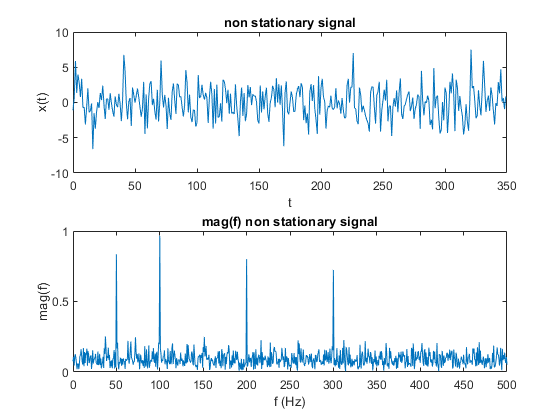

subplot(212), plot(f, half_mag_non_stationary_signal);
title('mag(f) non stationary signal')
xlabel('f (Hz)'), ylabel('mag(f)');

Indeed, it can be noted that in the case of a stationary signal, the spectrum analysis is more difficult due to this additional "noise". Indeed, in this case, it is possible to confuse the small amplitude frequency components with the noise surrounding them. Therefore, for non-stationary signals it is recommended to use a different transformation that allows a more accurate analysis of the spectrum.

## SHORT TIME FOURIER TRANSFORM

The STFT, compared to the FT, allows a more accurate analysis of the spectrum of the corresponding signal.

Calculate the STFT and plot it in different ways

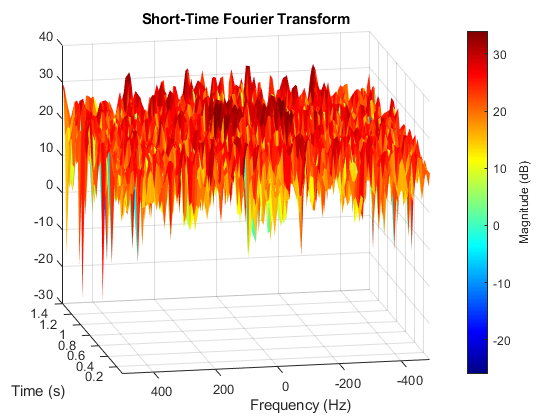

figure, stft(non_stationary_signal, fs), view(-45,65);
colormap jet;
view([-101.2 15.6])

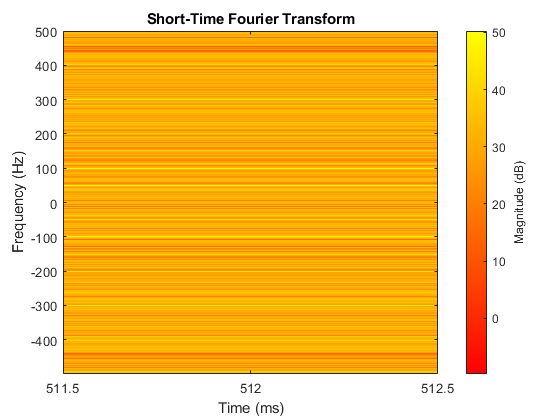

d = seconds(1e-3);
window = hamming(1024,'periodic');
figure, stft(non_stationary_signal,d, 'Window',window, 'OverlapLength',98,'FFTLength',2048);
colormap('autumn');

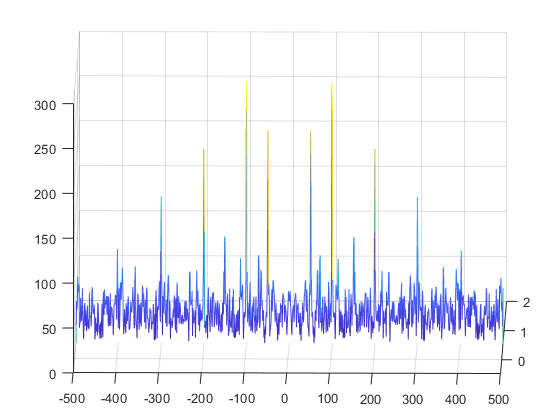

[S,F,T] = stft(non_stationary_signal,fs, 'Window',hamming(1024,'periodic'), 'OverlapLength',50);
figure, waterfall( F, T , abs(S(:,:,1))' );
view([0.9 15.1]);